% Define the file path (change 'your_file_path' to the actual path of your Excel file)
filename = 'ADC_Rawdata.xlsx';
% Load the data from the Excel file
data = readtable(filename);

% Extract individual variables by converting the table data to arrays using curly braces

% Trial 1
id_psu1 = data{1:31, 2};              % ID measured by power supply
Vid_scope1 = data{1:31, 5};           % voltage from hall effect sensor measured with oscilloscope
Vid_dn1 = data{1:31, 9};              % voltage from hall effect sensor measured with ADC
id_scope1 = (Vid_scope1 - 0.5) / 0.8; % current calculated from Vid
id_dn1 = (Vid_dn1 - 0.5) / 0.8;       % current calculated from Vid_scope

id_dn1_error = (id_psu1 - id_dn1) % total system error, difference between PSU value and ADC value

id_dn1_error =     0.0076
    0.0036
   -0.0035
   -0.0132
   -0.0308
   -0.0294
   -0.0277
   -0.0120
   -0.0188
   -0.0344


id_dn1_error_percent = ((id_psu1 - id_dn1)./(id_psu1)).*100

id_dn1_error_percent =        Inf
    6.8184
   -3.4369
   -8.6348
  -15.6958
  -11.6235
   -9.1576
   -3.3966
   -4.6566
   -7.5836



% Trial 2
id_psu2 = data{35:65, 2};
Vid_scope2 = data{35:65, 5};
Vid_dn2 = data{35:65, 9};
id_scope2 = (Vid_scope2 - 0.5) / 0.8;
id_dn2 = (Vid_dn2 - 0.5) / 0.8;

% Trial 3
id_psu3 = data{69:99, 2};
Vid_scope3 = data{69:99, 5};
Vid_dn3 = data{69:99, 9};
id_scope3 = (Vid_scope3 - 0.5) / 0.8;
id_dn3 = (Vid_dn3 - 0.5) / 0.8;

% Trial 4
id_psu4 = data{103:133, 2};
Vid_scope4 = data{103:133, 5};
Vid_dn4 = data{103:133, 9};
id_scope4 = (Vid_scope4 - 0.5) / 0.8;
id_dn4 = (Vid_dn4 - 0.5) / 0.8;

% Average of all trials
id_psu_avg = (id_psu1 + id_psu2 + id_psu3 + id_psu4) / 4;
Vid_scope_avg = (Vid_scope1 + Vid_scope2 + Vid_scope3 + Vid_scope4) / 4;
Vid_dn_avg = (Vid_dn1 + Vid_dn2 + Vid_dn3 + Vid_dn4) / 4;
id_scope_avg = (id_scope1 + id_scope2 + id_scope3 + id_scope4) / 4;
id_dn_avg = (id_dn1 + id_dn2 + id_dn3 + id_dn4) / 4;

% Ideal values
id_ideal = id_psu_avg;

% Error calculation, uses averages of all trials
id_hall_err = (id_psu_avg - id_scope_avg); % hall effect error, difference between PSU value and scope value 
id_dn_err = (id_scope_avg - id_dn_avg); % ADC error, difference between scope value and ADC value
id_total_err = (id_psu_avg - id_dn_avg) % total system error, difference between PSU value and ADC value

id_total_err =    -0.0057
   -0.0041
   -0.0086
   -0.0191
   -0.0284
   -0.0233
   -0.0258
   -0.0119
   -0.0295
   -0.0330



id_total_err_percent = ((id_psu_avg - id_dn_avg)./(id_psu_avg)).*100

id_total_err_percent =       -Inf
   -7.9004
   -8.4384
  -12.6771
  -14.3021
   -9.3631
   -8.5892
   -3.3882
   -7.3365
   -7.3210


% Compensate using two point gain error calculation
y1 = id_dn_avg(5)

y1 = 0.2269

y2 = id_dn_avg(25)

y2 = 1.8531

x1 = id_psu_avg(5)

x1 = 0.1985

x2 = id_psu_avg(25)

x2 = 1.8017


gain_error = (y2 - y1)/(x2 - x1)

gain_error = 1.0143

offset_error = id_dn_avg(1) - id_psu_avg(1)

offset_error = 0.0057


% example compensation
ideal = id_psu_avg(10)

ideal = 0.4510

uncal_measured = id_dn_avg(10)

uncal_measured = 0.4840

cal_value = (uncal_measured * gain_error) - offset_error

cal_value = 0.4852


% try calibrating a trial
id_dn1_cal = (id_dn1 .* gain_error) + offset_error

id_dn1_cal =    -0.0020
    0.0558
    0.1138
    0.1743
    0.2357
    0.2922
    0.3412
    0.3760
    0.4335
    0.5001


id_dn1_cal_error = (id_psu1 - id_dn1_cal)

id_dn1_cal_error =     0.0020
   -0.0028
   -0.0108
   -0.0213
   -0.0397
   -0.0392
   -0.0382
   -0.0230
   -0.0305
   -0.0471


id_dn1_cal_error_percent = (id_dn1_cal_error ./ id_psu1) .* 100

id_dn1_cal_error_percent =        Inf
   -5.3369
  -10.4870
  -13.9400
  -20.2800
  -15.4902
  -12.6149
   -6.5033
   -7.5798
  -10.3917


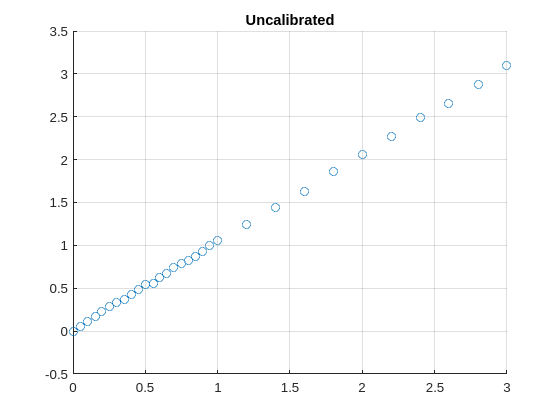


% compare datas 
figure;
scatter(id_psu1, id_dn1); title("Uncalibrated"); grid on;

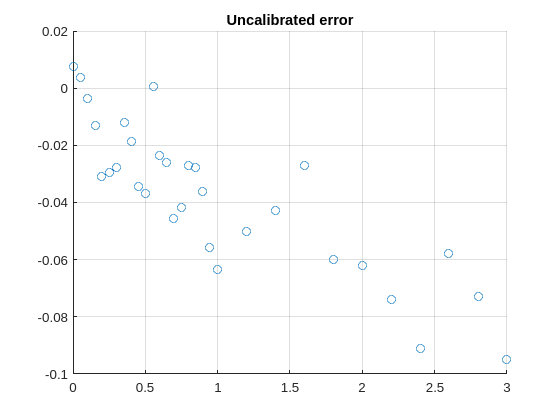

figure;
scatter(id_psu1, id_dn1_error); title("Uncalibrated error"); grid on;

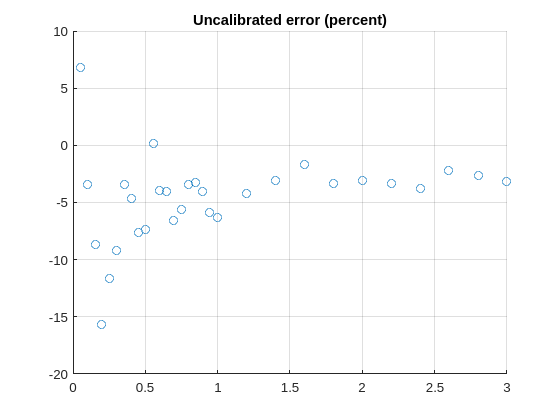

figure;
scatter(id_psu1, id_dn1_error_percent); title("Uncalibrated error (percent)"); grid on;

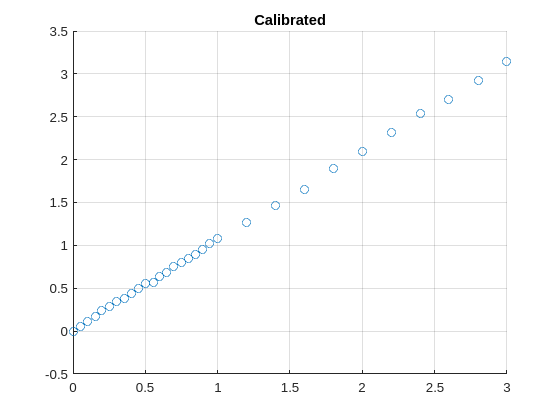


figure;
scatter(id_psu1, id_dn1_cal); title("Calibrated"); grid on;

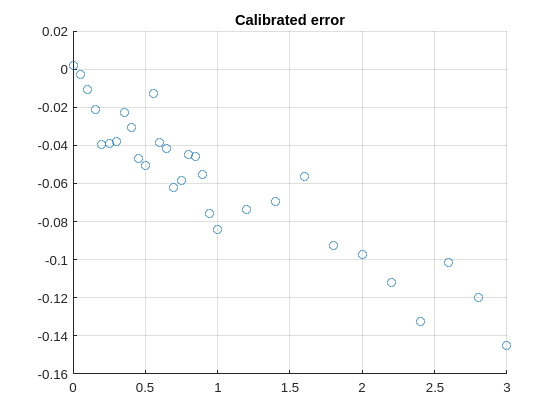

figure;
scatter(id_psu1, id_dn1_cal_error); title("Calibrated error"); grid on;

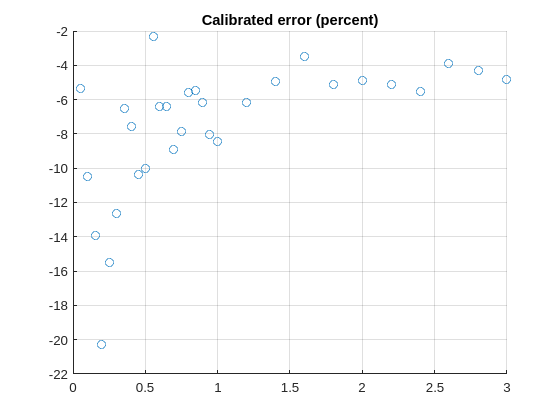

figure;
scatter(id_psu1, id_dn1_cal_error_percent); title("Calibrated error (percent)"); grid on;